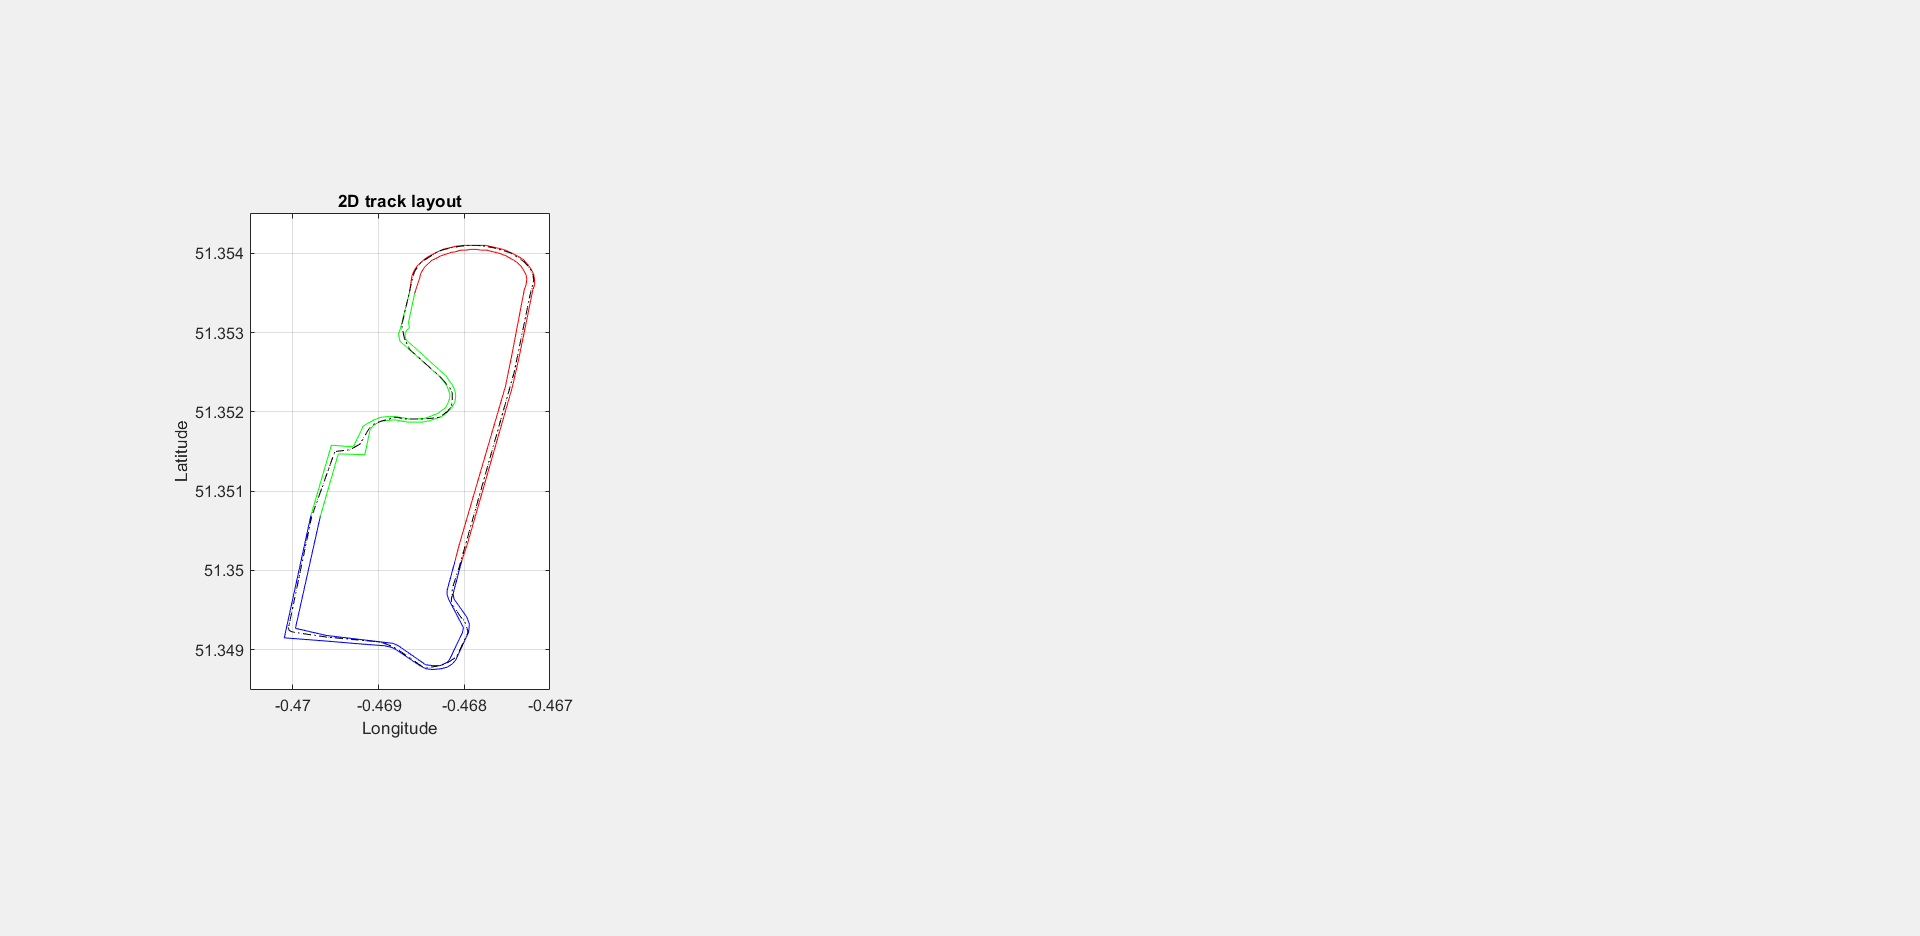

% 
clear;clc;close all;

gen_track();

RL = gen_RL("Ideal_Racing_Line.txt",'Ideal Racing Line');



t = [0:0.1:39*60]; laps = 1; strat = 1;
% [path, RL_all] = gen_path(t,laps, RL);

out = sim('New_model.slx','StopTime',num2str(t(length(t))));

[acc, vel, vol, epow, eenergy, mpow, menergy, cap, torque] = recover(out);
[path, RL_all] = gen_path(t,laps,RL,acc,vel);

1 laps completed in 250.60s 
2 laps completed in 458.10s 
3 laps completed in 661.80s 
4 laps completed in 863.80s 
4 laps completed in 863.90s 
5 laps completed in 1065.10s 
6 laps completed in 1266.00s 
7 laps completed in 1466.70s 
8 laps completed in 1667.30s 
8 laps completed in 1667.40s 
9 laps completed in 1867.90s 
9 laps completed in 1868.00s 
10 laps completed in 2068.50s 
10 laps completed in 2068.60s 
11 laps completed in 2269.10s 
11 laps completed in 2269.20s 


para = [vol epow eenergy cap];

% gen_ani(path, para,0);

% Calculate elec to mech efficiency
eff = menergy(length(t)) / eenergy(length(t)) * 100;
fprintf('Elec to Mech efficiency: %.2f%%', eff)

Elec to Mech efficiency: 67.77%